# A tutorial on how to use the Brain Observatory Toolbox

This tutorial will show you how to access the Brain Observatory data using MATLAB. In particular, this tutorial will show you how to:

1) Download meta information from brain observatory api and save it as MATLAB datatype

2) Build a brain_observatory_cache object to:

    A) Get general information on the brain observatory data

    B) Filter sessions by specified criteria such as brain areas, imaging depth and stimuli type

    C) Download Neurodata Without Borders (NWB) files of filtered sessions

3) Extract imaging data from NWB files to:

    a) Get and plot fluorescence traces

    b) Convert fluorescence trace into data that is in "raster format" for further analysis

## Organization of the Brain Observatory Data

Before we start, we first want to describe the organization of the Brain Observatory Data. 

An *experiment container* contains three *sessions* (also called *experiments* or *ophys_experiments*) where recordings were made on a singe mouse, in a single brain region and at a particular imaging depth. Each of these three sessions consists of a series of "subexperiments" where a particular stimulus set was shown. Neurodata Without Borders (NWB) files downloaded from the Allen Institute API each consist of data from a single session. As described below, all data that we extract into "raster format" consists of data from a single "subexperiment" where a particular stimulus set was shown. 

Note: within an experiment container the same stimuli might be repeated in different sessions (i.e., different sessions can have the same "subexperiment type").  For example, Natural Movie 1 is shown in all three sessions in an experiment container. For more information see: [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

## 1) Download meta information from brain observatory api and save it as MATLAB datatype

To begin, add the path to Brain Observatory Toolbox:

bot_dir_name = '../Brain-Observatory-Toolbox/';
addpath(bot_dir_name)

Next we will download the meta information which is stored in manifest files on the Allen API.  We can do this using the function get_manifests_info_from_api(). This function creates a MATLAB structure array with three tables and saves this structure array in a file called manifests.mat; manifests.mat will be used as an argument to the brain_observatory_cache as shown in the next section.

get_manifests_info_from_api()  % this should take around a minute to run in order to download the files

Elapsed time is 0.000814 seconds.


load('manifests')

manifests  % view the tables in the manifests structure 

There are three tables in manifest.mat: 

- *container_manifest contains* metadata of all experiment containers (m containers by n aspects of meta data)

- *session_manifest *contains metedata of all sessions (m sessions by n aspects of meta data), and 

- *cell_id_mapping* contains mapping between new cell ids and the old cell id of all cells (m cells by number of ids).

Note: The reason there is a mapping between ... As quoted from AllenSDK 's release note (0.13.2): "The cross-session alignment algorithm has been updated and re-run, so all cell specimen IDs have changed".

## 2) Build a brain_observatory_cache object

Brain_observatory_cache is a class that resembels BrainObservatoryCache in allensdk (see Python code at:[https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py](https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py)).

The MATLAB brain_observator_cache takes manifest files and enables you to get information and access data using three types of methods:

A) Get general information on the brain observatory data using methods that start with "get_" 

B) Filter sessions by different criteria using methods that start with "filter_"

C) Download NWB file(s) of filtered session(s) using method named "download_nwb"

To beign, build a brain_observatory_cache_object

boc = brain_observatory_cache(manifests)

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [597×14 table]
                   stimuli: {1×17 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [597×1 double]
              session_type: {4×1 cell}


As you can see here, the data in manifests.mat is stored in the brain_observatory_cache properties *manifets.session_manifest,* *manifets.session_table,* and *manifets.container_manifest. *The other properties in the brain_observatory_cahce will be explained below.

## 2A) Get general information on the brain observatory data

There are several methods whose names start with "get_" which summairze in the brain observatory data based on particular criteria. 

To get the total number of experiment containers we can use:

boc.get_total_num_of_containers()

ans = 199

Note: Total number of sessions is the number of containers times 3 since there are three sessions per container.

To get all the cortical depths that were ever recorded in any experiment container we can use:

boc.get_all_imaging_depths()

ans =    175
   265
   275
   300
   320
   325
   335
   350
   365
   375


Note: Recordings didn't take place equally among these depths, only the most common depths are shown on homepage of Brain Observatory: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

To get all the get all type of cre driver lines from all mice we can use:

boc.get_all_cre_lines()

ans = 6×1 cell array
    'Cux2-CreERT2'
    'Emx1-IRES-Cre'
    'Nr5a1-Cre'
    'Rbp4-Cre_KL100'
    'Rorb-IRES2-Cre'
    'Scnn1a-Tg3-Cre'


Note: All mice had the same reporter line: Ai93 and tTA driver line: Camk2a-tTA

For more information about transgenic lines: [http://observatory.brain-map.org/visualcoding/transgenic](http://all mice had the same reporter line: Ai93 and driver line: Camk2a-tTA; there were several cre lines as shown here. % for more information about transgenic lines: http://observatory.brain-map.org/visualcoding/transgenic)

To get all the all brain regions that were recorded in any experiment container we can use:

boc.get_all_targeted_structures()

ans = 6×1 cell array
    'VISal'
    'VISam'
    'VISl'
    'VISp'
    'VISpm'
    'VISrl'


For more information on these locations, see homepage of Brain Observatoy: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

To get all the all types of sessions that appear in any experiment container we can use:

boc.get_all_session_types()

ans = 4×1 cell array
    'three_session_A'
    'three_session_B'
    'three_session_C'
    'three_session_C2'


Note: There are always three sessions in each container: session A, session B,  and session C or session C2

To get all the  all type of stimuli that were used in any of the four types of sessions we can use:

boc.get_all_stimuli()

ans = 9×1 cell array
    'drifting_gratings'
    'locally_sparse_noise_eight_degree'
    'locally_sparse_noise_four_degree'
    'natural_movie_one'
    'natural_movie_three'
    'natural_movie_two'
    'natural_scene'
    'spontaneous_activity'
    'static_gratings'


Note: For mapping between session type and stimulus type see [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

To get the numer of experiment containers recorded in each brain region we can use:


boc.get_summary_of_containers_along_targeted_structures()

     VISal      33 
     VISam      25 
     VISl       36 
     VISp       54 
     VISpm      35 
     VISrl      16 


To get the numer of experiment containers recorded at each cortical depth we can use:

boc.get_summary_of_containers_along_imaging_depths()

     175      50 
     265       1 
     275      72 
     300       4 
     320       1 
     325       3 
     335       3 
     350      33 
     365       1 
     375      30 
     435       1 


To get the number of experiment containers recorded at each cortical depth in each brain region we can use:

boc.get_summary_of_containers_along_depths_and_structures()

ans = 12×7 table
             VISal    VISam    VISl    VISp    VISpm    VISrl    total
             _____    _____    ____    ____    _____    _____    _____

    175       8        5       10      11      11        5        50  
    265       1        0        0       0       0        0         1  
    275      12        9       15      20      11        5        72  
    300       1        0        1       1       1        0         4  
    320       0        1        0       0       0        0         1  
    325       0        1        1       0       1        0         3  
    335       0        0        0       2       1        

## 2B) Filter sessions by specified criteria such as brain areas, imaging depth and stimuli type

"Filter methods" reduce the meta data in the brain_observatory_cache's `filter_session_table` based on particular criteria. To illustrate this, let's start by creating a new  clean brain_observatory_cache object:

boc = brain_observatory_cache(manifests)    

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [597×14 table]
                   stimuli: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [597×1 double]
              session_type: {4×1 cell}


Note that this brain_observatory_cache object has a property named `session_table` and a property `named ``filtered_session_table``. When the brain_observatory_cache object is first created, both of these properties are initialized to the same `[597x14] dimensional table, where the number 597 refers to the total number of sessions that have currently been made available by the Allen Instutute. As different filter methods get called on the brain_observatory_cahce object, rows in the `filtered_session_table `are liminated to meet specified criteria, and the other properies in the brain_observatory_cahce object are also updated.  

Here we show an example of searching for sessions that primary visual cortex was  recorded at 275 mm deep and during where drifting gratings were shown.

Eliminate information to only sessions where drifting gratings were shown:

boc.filter_sessions_by_stimuli('drifting_gratings')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [199×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [199×1 double]
              session_type: {'three_session_A'}


Note that all properties of the brain_observatory_cache object have changed except the first top three properties.

Eliminate information to only sessions that have posterior Primary Visual Cortex recoredings:

boc.filter_sessions_by_targeted_structure('VISp')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [54×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [6×1 double]
              container_id: [54×1 double]
                session_id: [54×1 double]
              session_type: {'three_session_A'}


Eliminate information to only sessions that were recoreded at 275 mm deep

boc.filter_sessions_by_imaging_depth(275)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [20×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: [20×1 double]
                session_id: [20×1 double]
              session_type: {'three_session_A'}


As we can see now, there are 20 sessions that met all of the criteria given. 

Every experiment container in the Brain Obervatory has an unique experiment ID that was created by the Allen Institute. These container IDs by looking at the experiment_container_id field in `session_table `or `filtered_session_table`.  For example, to see the 20 experiment container IDs that met our filtering criteria we can run: 

boc.filtered_session_table.experiment_container_id

ans =    527550471
   511510675
   528959519
   527676429
   511506664
   530243910
   511510779
   511510927
   524691282
   511510667


Let's now filter the to only contain information from the first experiment session container (experiment session ID 527550471), which wil lmake the code run much faster when we download the two-photon imaging data in the next stage.

boc.filter_sessions_by_container_id(527550471)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [1×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: 527550471
                session_id: 527745328
              session_type: {'three_session_A'}


Take a look at metedata of the final filtered session we can see all the properties that are associated with this session: 

boc.filtered_session_table

ans = 1×14 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth              name              specimen_id      stimulus_name                                    storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen  
    ______________________    _______________________    _________________    __________    _____________    ________________________    ___________    _________________    _____________________________________________________________________

Note there is only one row in this table because only one of the sessions in the experimental container 527550471 met our other filter criteria. If we create a new brain_observatory_cache object called boc2 and only use the boc2.filter_sessions_by_container_id(527550471) method, then there will be three rows corresponding to the three session in the experiment container. 

boc2 = brain_observatory_cache(manifests);
boc2.filter_sessions_by_container_id(527550471);
boc2.filtered_session_table

ans = 3×14 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth              name              specimen_id      stimulus_name                                    storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen  
    ______________________    _______________________    _________________    __________    _____________    ________________________    ___________    _________________    _____________________________________________________________________

Note, brain_observatory_cache object is not merely useful for helping to get NWB files to download, but it can also be used to retrieve information about files you have already downloaded in case you need to find more information about these files. 

## 2C) Download NWB files of filtered session(s)

Finally real data stored in Neurodata Without Borders (NWB) files. More information about NWB files can be found at:

- Their github page: [http://neurodatawithoutborders.github.io/](http://neurodatawithoutborders.github.io/)

- A publication about the data format: [http://www.sciencedirect.com/science/article/pii/S0896627315009198](http://www.sciencedirect.com/science/article/pii/S0896627315009198)

Let's begin by creating a variable that has the directory name where the NWB files will be saved. 

nwb_dir_name = [bot_dir_name,'nwb_files/'];

We can then call the brain_observatory_cache method `download_nwb() `to dowload all NWB file(s) corresponding to filtered session(s) stored in brain_observatory_cache and save then in the specified directory:

boc.download_nwb(nwb_dir_name);

downloading the nwb filethe new nwb file is finally donwloadedElapsed time is 1506.533837 seconds.


Elapsed time is 1506.542726 seconds.


Note: The size of a NWB files are around 600MB, and take 25 minutes to download on our system, so you might want to take a break and get some coffee. Once the file has been downloaded brain_observatory_cache will return a message the the file has been downloaded.

## 3) Import imaging data from NWB files

Now we have downloaded an NWB file, we can extract the florescence traces from the file and convert them to data in "raster format"  which makes the data easier to analyze. For more info about raster format, see [http://www.readout.info/toolbox-design/data-formats/raster-format/](http://www.readout.info/toolbox-design/data-formats/raster-format/)

## 3a) Get and plot fluorescence traces

Before we start converting data to raster format, let us plot some fluorescence traces to make sure the data looks reasonable. The Brain Observatory NWB files contain fluroescent traces in 4 different stages of processing from raw to fully processes, which are called: raw, demixed, neuropil corrected, Df over F. We can plot these traces in two different ways by either:

     i) Extracting the fluorescence traces of all cells in one session and then plotting them using general MATLAB plotting functions 

     ii) Using the Brain Observatory Toolbox's `plot_fluorescence_traces()` function.

Here we show an example of i):

    Extract and compute all four types fluorescence traces available in the NWB file of session 517745328 and save them to the worksapce.

session_id  = 527745328;
[raw, demixed, neuropil_corrected, DfOverF] = extract_fluorescence_traces_from_NWB_file(nwb_dir_name, session_id);

Elapsed time is 4.300502 seconds.


This function returns a [num_cells x num_time] sized matrix for eact of the types of flourescence trace extracted. We can plot the first flourescence trace of the raw signal using: 

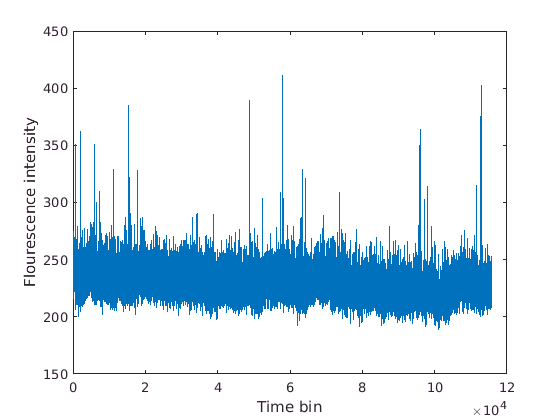

plot(raw(:, 1))
xlabel('Time')
ylabel('Flourescence intensity')

Alternatively, as an example of method ii, we can use the plot_fluorecence_traces() function to plot the traces of a cell with id 529022196 in session 527745328 directly using:

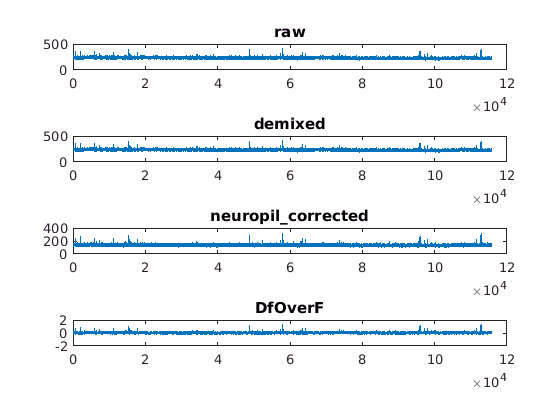

session_id  = 527745328;
cell_id = 529022196;
plot_fluorecence_traces(nwb_dir_name, session_id,cell_id);

## 3b) Convert fluorescence trace into data in "raster format" 

We will now save the fluorescence traces to raster format. To start, let us specify the path where directories containing raster files will be saved:

raster_dir_name = [bot_dir_name, 'raster/'];

We can then use the `convert_fluorescenece_trace_into_raster_format() `function to create the raster data by specifying the session ID, the type of stimuli you are interested in, and the type of fluorescence trace you want to use, along with the directory names for the nwb_files and raster_data: 

session_id  = 527745328;
stimuli = 'drifting_gratings';
fluorescence_trace = 'DfOverF';

current_raster_dir_name = convert_fluorescenece_trace_into_raster_format(nwb_dir_name, raster_dir_name, fluorescence_trace,...
    session_id, stimuli);

../Brain-Observatory-Toolbox/raster/drifting_gratings_527745328/ already exists

## 4) Get Masks...